Maximum F = 436.2𝑘𝑁

clear all
clf
N_top = 2.1499e5; %N
M_top = 11.638; %Nm
N_midt = 2.4088e5; %N
M_midt = 85.326; %Nm
N_bot = 2.3954e5; %N
M_bot = 86.191; %Nm

N = [N_top, N_midt, N_bot];
M = [M_top, M_midt, M_bot];
d = 0.024; %m bolt diameter
A_t = 353e-6; %tensile stress area %pi*(d/2)^2
A_test = pi*(d/2)^2

A_test =      4.523893421169302e-04


S_N1 = N/A_t

S_N1 = 1.0e+08 *

   6.090368271954674   6.823796033994333   6.785835694050991



I = pi * d^4 / 64

I =      1.628601631620949e-08


y = d/2; %armen til momentet
S_N2 = M * y / I

S_N2 = 1.0e+07 *

   0.857520938751610   6.287062349194009   6.350798009274792



S_max = S_N1 + S_N2

S_max = 1.0e+08 *

   6.176120365829835   7.452502268913735   7.420915494978471


Minimum F = 43.6𝑘𝑁

N_top = 2.0714e5; %N
M_top = 2.8462; %Nm
N_midt = 2.0631e5; %N
M_midt = 3.1656; %Nm
N_bot = 2.0675e5; %N
M_bot = 5.7774; %Nm

N = [N_top, N_midt, N_bot];
M = [M_top, M_midt, M_bot];

A_t = 353e-6; %tensile stress area %pi*(d/2)^2
% d = 0.024; %m bolt diameter
d = sqrt(A_t*4/pi)

d =    0.021200319792199


% A_test = pi*(d/2)^2
S_N1 = N/A_t

S_N1 = 1.0e+08 *

   5.867988668555241   5.844475920679886   5.856940509915015



I = pi * d^4 / 64

I =      9.916069151868994e-09


y = d/2; %armen til momentet
S_N2 = M * y / I

S_N2 = 1.0e+06 *

   3.042553922749938   3.383988721051649   6.175971833776787



S_min = S_N1 + S_N2

S_min = 1.0e+08 *

   5.898414207782740   5.878315807890403   5.918700228252783


Stress range $\Delta\sigma$

DS = S_max - S_min %stress range Pa

DS = 1.0e+08 *

   0.277706158047094   1.574186461023332   1.502215266725688


Den mest kritiske bolt er midter bolten da den har størst stress range

curve data load 0 to 500kN

% clear all
% clf
% % Define the filename and range
% filename = 'D:\Mathias\OneDrive\Mathias uddannelse\Ingeniør\Maskinteknik\6. Semester\Avanceret udmattelseslære\Opgaver\Opgave 12\Heat exchanger experiments data.xlsx';
% % filename = 'C:\AU onedrive\OneDrive - Aarhus universitet\Varmetransmission\Heat exchanger experiments data.xlsx';
% 
% 
% range = 'G19:L19';
% exp2_test1 = xlsread(filename, range) % Import data from Excel file
clf
F = [0, 100, 200, 300, 400, 500];
N_0 = 2.200e5;	
M_0 = 4.067;
N_100 = 2.056e5;	
M_100 = 2.707;
N_200 = 2.084e5;	
M_200 = 13.26;
N_300 = 2.133e5;	
M_300 = 36.24;
N_400 = 2.348e5;
M_400 = 66.35;
N_500 = 2.550e5;	
M_500 = 119.7

M_500 =         119.7


N = [N_0, N_100, N_200, N_300, N_400, N_500];
M = [M_0, M_100, M_200, M_300, M_400, M_500];

A_t = 353e-6; %tensile stress area %pi*(d/2)^2
% d = 0.024; %m bolt diameter
d = sqrt(A_t*4/pi)

d =        0.0212


% A_test = pi*(d/2)^2
S_N1 = N/A_t

S_N1 =    6.2323e+08   5.8244e+08   5.9037e+08   6.0425e+08   6.6516e+08   7.2238e+08



I = pi * d^4 / 64

I =    9.9161e-09


y = d/2; %armen til momentet
S_N2 = M * y / I

S_N2 =    4.3476e+06   2.8938e+06   1.4175e+07    3.874e+07   7.0927e+07   1.2796e+08



S = S_N1 + S_N2

S =    6.2758e+08   5.8533e+08   6.0454e+08   6.4299e+08   7.3608e+08   8.5034e+08



plot(F,S/1e6,'--o', DisplayName='Stresses from SW test')
hold on
xlabel('Applied total force (kN)')
ylabel('Stress on critical bolt $\sigma$(MPa)', Interpreter='latex')
grid("on")

F_lin = linspace(0,500,100);
S_lin = interp1(F,S,F_lin, 'pchip'); % interpolere

p = polyfit(F,S,length(F)-1)

p =   -0.00012212      0.15447      -69.189        14849  -1.3577e+06   6.2758e+08


[P_poly,S_pol] = polyfit(F,S,length(F)-1)

P_poly =   -0.00012212      0.15447      -69.189        14849  -1.3577e+06   6.2758e+08


S_pol = struct with fields:
        R: [6×6 double]
       df: 0
    normr: 4.7385e-06


P_poly

P_poly =   -0.00012212      0.15447      -69.189        14849  -1.3577e+06   6.2758e+08


S_pol

S_pol = struct with fields:
        R: [6×6 double]
       df: 0
    normr: 4.7385e-06


help polyfit

 polyfit Fit polynomial to data.
    P = polyfit(X,Y,N) finds the coefficients of a polynomial P(X) of
    degree N that fits the data Y best in a least-squares sense. P is a
    row vector of length N+1 containing the polynomial coefficients in
    descending powers, P(1)*X^N + P(2)*X^(N-1) +...+ P(N)*X + P(N+1).
 
    [P,S] = polyfit(X,Y,N) returns the polynomial coefficients P and a
    structure S for use with POLYVAL to obtain error estimates for
    predictions.  S contains these fields:
 
          R  -  Triangular R factor (possibly permuted) from a QR
                decomposition of the Vandermonde matrix of X
         df  -  Degrees of freedom
      normr  -  Norm of the residuals
 
    If the data Y are random, an estimate of the covariance matrix of P is
    (Rinv*Rinv')*normr^2/df, where Rinv is the inverse of R.
 
    [P,S,MU] = polyfit(X,Y,N) finds the coefficients of a polynomial in
    XHAT = (X-MU(1)

syms S_int_poly(x) x
S_int_poly(x) = 0;

N = length(p);
for i = 1:N
    S_int_poly(x) = S_int_poly(x) + p(i)*x^(N-i);  
end
S_int_poly(x)

$$ans = -\frac{4505361313975603\,x^{5}}{36893488147419103232}+\frac{5565310522122591\,x^{4}}{36028797018963968}-\frac{608595634307653\,x^{3}}{8796093022208}+\frac{8163203394341727\,x^{2}}{549755813888}-\frac{728915948859049\,x}{536870912}+\frac{5264497747728461}{8388608}$$

plot(F_lin,S_lin/1e6, DisplayName='Stresses interpolated')
legend(Location='Best')

S_poly = polyval(p, F_lin)

S_poly =    6.2758e+08   6.2109e+08   6.1531e+08   6.1018e+08   6.0566e+08   6.0171e+08   5.9827e+08   5.9531e+08    5.928e+08   5.9068e+08   5.8893e+08   5.8752e+08   5.8641e+08   5.8558e+08     5.85e+08   5.8464e+08   5.8448e+08    5.845e+08   5.8468e+08   5.8499e+08   5.8543e+08   5.8597e+08    5.866e+08   5.8732e+08    5.881e+08   5.8894e+08   5.8983e+08   5.9076e+08   5.9172e+08   5.9272e+08   5.9374e+08   5.9478e+08   5.9584e+08   5.9692e+08   5.9802e+08   5.9913e+08   6.0027e+08   6.0142e+08    6.026e+08   6.0381e+08   6.0504e+08   6.0631e+08   6.0762e+08   6.0897e+08   6.1037e+08   6.1183e+08   6.1335e+08   6.1494e+08    6.166e+08   6.1835e+08


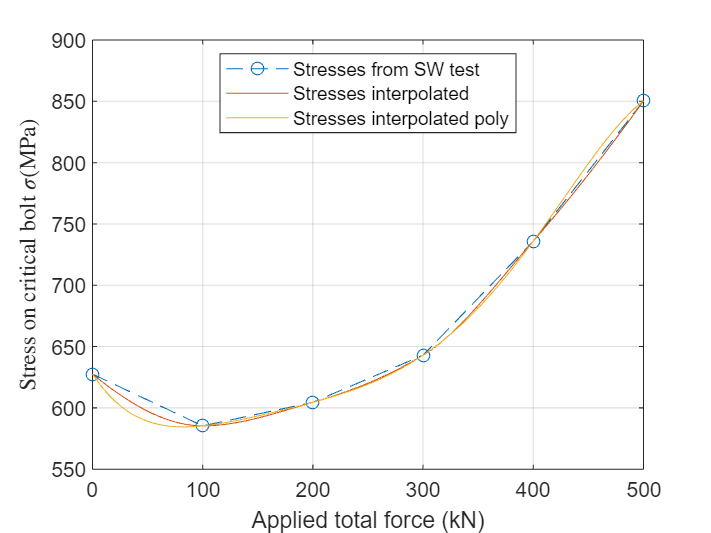

plot(F_lin,S_poly/1e6, DisplayName='Stresses interpolated poly')

hold off


Fs = [43.6, 436.2];
S_int = interp1(F,S,Fs, 'pchip');

S_int_poly_val = polyval(p, Fs)

S_int_poly_val =    5.9141e+08   7.8194e+08


double(S_int_poly(Fs))

ans =    5.9141e+08   7.8194e+08



S_min_int = S_int(1)

S_min_int =    6.0037e+08


S_max_int = S_int(2)

S_max_int =    7.7484e+08


Finding the life cyles with EC3-1-9 DC50.

N_start = 1e4;
N_DC = 2e6;
dS_DC = 50;
N_D = 5e6;
N_L = 1e8;
m1 = 3;
m2 = 5;

C1 = dS_DC^m1 * N_DC;
syms dS_D_sym
dS_D_eq = C1 == dS_D_sym^m1 * N_D;
dS_D = solve(dS_D_eq, dS_D_sym);
dS_D = double(dS_D(1))

dS_D =   36.840314986403868



syms dS_start_sym
dS_start_eq = C1 == dS_start_sym^m1 * N_start;
dS_start = solve(dS_start_eq, dS_start_sym);
dS_start = double(dS_start(1))

dS_start =      2.924017738212866e+02



C2 = dS_D^m2 * N_D;

syms dS_L_sym
dS_L_eq = C2 == dS_L_sym^m2 * N_L;
dS_L = solve(dS_L_eq, dS_L_sym);
dS_L = double(dS_L(1))

dS_L =   20.235658223516172


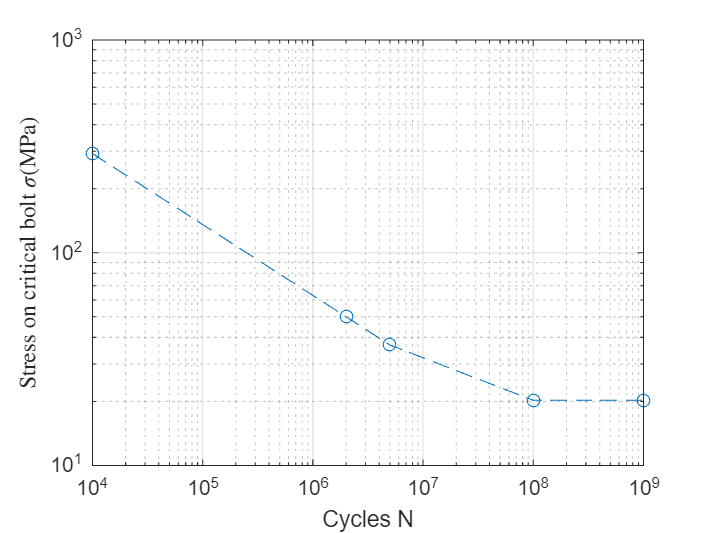


dSs = [dS_start, dS_DC, dS_D, dS_L, dS_L];
Ns = [N_start, N_DC, N_D, N_L, 1e9];

loglog(Ns, dSs,'--o')
xlabel('Cycles N')
ylabel('Stress on critical bolt $\sigma$(MPa)', Interpreter='latex')
ylim([10,1000])
grid("on")

estemated life

format shortg
DS = (S_max - S_min)/1e6; %converting to MPa
% N_life = [];
for i = 1:length(DS)
    if DS(i) > dS_D
        m = m1;
        C = C1;
    else
        m = m2;
        C = C2;
    end
    syms N_sym; assume(N_sym, 'real'); assume(N_sym, 'positive')
    N_eq = C == DS(i)^m * N_sym;
    N = solve(N_eq, N_sym);
    N_life(i) = double(N(1))
end

N_life =    2.0543e+07


N_life =    2.0543e+07        64087


N_life =    2.0543e+07        64087        73747



N_life_top = N_life(1)

N_life_top =    2.0543e+07


N_life_midt = N_life(2)

N_life_midt =         64087


N_life_bot = N_life(3)

N_life_bot =         73747


b) The structure was tested and endured 169.800 load cycles before the bolts fractured under the

above load [1]. Compare your calculations with this value.

It would not hold then since i got less then half the cyles, my estimate is very conservative

c) Create a plot of the bolt stress as a function of the external load in the range 𝐹 = 0 − 500𝑘𝑁 for the critical bolt and explain how you could use this nonlinear transfer function for VA loading.